# 1 DOF Pitch Control Design

Recall the 1 DOF Aero open-loop transfer function 


$$P(s) = \frac{\Theta(s)}{\Omega_p(s)} = \frac{ \frac{D_tK_{pp}}{J_p} } {s^2 + \frac{D_p}{J_p}s + \frac{K_{sp}}{J_p}}$$


The input-output relation in the time-domain for a PID controller is


$$u=k_p(\theta_d-\theta)+k_i \int{(\theta_d-\theta) \, dt}-k_d \dot{\theta}$$


where $k_p
$ is the proportional gain, $k_i$ is the integral gain, $k_d$ is the derivative gain, and $\theta_d$ is the desired pitch angle. Remark that only the measured velocity is used, i.e. instead of using the derivative of the error. 

Applying this to the open-loop transfer function we obtain the closed loop transfer function is


$$G_{\theta,d}(s)=\frac{\Theta(s)}{\Theta_d(s)} = \frac{K_t D_t (k_p s+k_i)}{J_p s^3 + (D_p +D_t K_t k_d)s^2+(K_{sp} +D_t K _t k_p) s + D_t K_t k_i}$$


The prototype third-order characteristic polynomial is


$$		(s^2+2\zeta\omega_ns+\omega_n^2)(s+p_0)=s^3+(2\zeta\omega_n+p_0)s^2+(\omega_n^2+2\zeta\omega_np_0)s+\omega_n^2p_0$$


where $\omega_n$ is the natural frequency, $\zeta$is the damping ratio, and $p_0$ is the pole location.

The characteristic equation in closed-loop transfer function, can match the desired characteristic equation with the following gains


$$k_p = \frac{-K_{sp}+2 J_p p_0 \zeta \omega_n + J_p \omega_n^2}{D_t K_t}$$



$$k_i = \frac{p_0 J_p \omega_n^2}{D_t K_t}$$



$$k_d = \frac{-D_p+p_0 J_p +2 J_p \zeta \omega_n }{D_t K_t}$$


## Aero 2 Pitch Model

Aero 2 Parameters

aero2_parameters;

Load stiffness, damping, and thrust parameter values that you found in the *Parameter Estimation *lab.

% Stiffness (N.m/rad)
Ksp = 0.0130;
% Damping (N.m/(rad/s))
Dp = 0.00172; 
% Pitch thrust gain (N/(rad/s))
Kpp = 2.84e-4; 

Load 1 DOF pitch model give above.

pitchTF = tf(Dt*Kpp/Jp,[1 Dp/Jp Ksp/Jp])

pitchTF =
 
          0.002051
  ------------------------
  s^2 + 0.07417 s + 0.5606
 
Continuous-time transfer function.



## Control Design and Simulation

Desired time-domain specifications.

% Peak time (s)
tp = 3.5;
% Percent overshoot (%)
PO = 5;
% Damping ratio from overshoot specification.
zeta = -log(PO/100) * sqrt( 1 / ( ( log(PO/100) )^2 + pi^2 ) );
% Natural frequency from specifications (rad/s)
wn = pi / ( tp * sqrt(1-zeta^2) );
% Desired zero location for control design
p0 = 0.4;

**Student Exercise**: Enter the PID equations to calculate the gain needed to satisfy the specifications. 

% Default PID gains
kp = 500;
ki = 300;
kd = 700;

#### Simulink Simulation

Run the Simulink model to simulate the closed-loop response. 

- Evaluate that the specifications are matched in simulation using the full Aero 2 model that includes the rotor and pitch dynamics as well as motor limits (i.e., 0 to 24V).

- If the specifications are met, implement on hardware.

% Simulated closed-loop PID control using full model w/ actuator limits
open("s_aero2_pid.slx");
% sim("s_aero2_pid.slx");

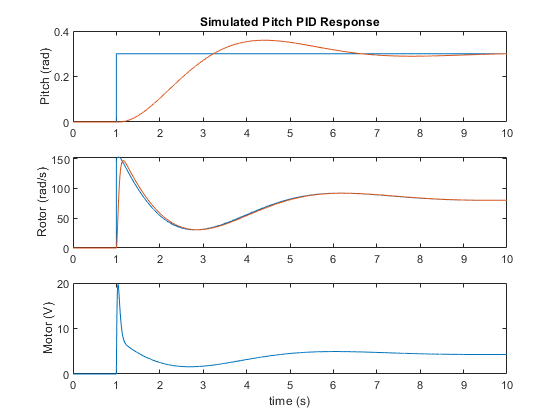

% plot results saved in Scope variables
t = DataPitchPIDSimTheta.time;
ydsim = DataPitchPIDSimTheta.signals(1).values;
ysim = DataPitchPIDSimTheta.signals(2).values;
wd_sim = DataPitchPIDSimRotor.signals(1).values;
wm_sim = DataPitchPIDSimRotor.signals(2).values;
usim = DataPitchPIDSimVp.signals.values;
% 
figure;
subplot(3,1,1);
plot(t,ydsim,t,ysim); 
title('Simulated Pitch PID Response')
ylabel('Pitch (rad)');
subplot(3,1,2);
plot(t,wd_sim,t,wm_sim);
ylabel('Rotor (rad/s)');
subplot(3,1,3);
plot(t,usim);
ylabel('Motor (V)');
xlabel('time (s)')

Measure response control specifications.

% expected final value
yfinal_sim = max(ydsim);
% get step info
stepinfo(ysim,t,yfinal_sim)

ans = struct with fields:
        RiseTime: 1.4774
    SettlingTime: 8.9183
     SettlingMin: 0.2701
     SettlingMax: 0.3593
       Overshoot: 19.7763
      Undershoot: 0
            Peak: 0.3593
        PeakTime: 4.4120


### Aero 2 Control Implementation

#### Virtual Aero 2 Configuration

- Run the Quanser Interactive Labs (QLabs) software and load the Aero 2 *Workspace*.

- Launch MATLAB and browse to the working directory that includes the Simulink models for this lab.

- Configure the Aero 2 in the 1 DOF VTOL / Pitch only configuration: 

- **Unlock** the pitch axis and **lock **the yaw axis.

- Both the front and rear rotors are **horizontal**.

If you have any issues running the software, please go to the [QLabs support page](https://portal.quanser.com/Support).

Run the following Simulink model to implement the closed-loop control on the Virtual Aero 2 using QLabs.

open("virtual_aero2_pid.slx");

Plot measured data saved by the Simulink model. The data logging is performed in the Simulink Scopes.

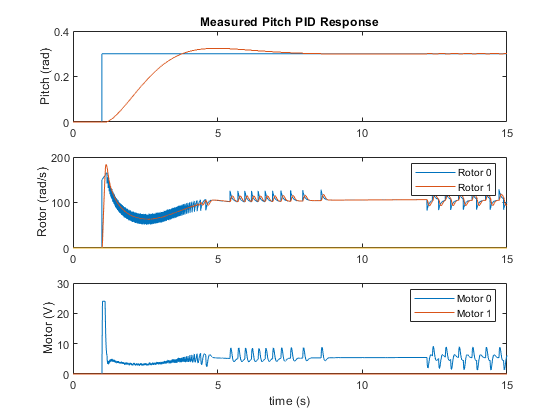

% load data into variables
t = DataPitchPIDTheta.time;
theta_d = DataPitchPIDTheta.signals(1).values;
theta = DataPitchPIDTheta.signals(2).values;
wm_d = DataPitchPIDRotor.signals(1).values;
wm0 = DataPitchPIDRotor.signals(2).values;
wm1 = DataPitchPIDRotor.signals(3).values;
u0 = DataPitchPIDVm.signals(1).values;
u1 = DataPitchPIDVm.signals(2).values;
% 
figure
subplot(3,1,1);
plot(t,theta_d,t,theta);
title('Measured Pitch PID Response')
ylabel('Pitch (rad)');
subplot(3,1,2);
plot(t,wm_d,t,wm0,t,wm1);
ylabel('Rotor (rad/s)');
legend('Rotor 0','Rotor 1');
subplot(3,1,3);
plot(t,u0,t,u1);
ylabel('Motor (V)');
legend('Motor 0','Motor 1');
xlabel('time (s)');